# Compressor Test Script

% Author: Nicholas Tong
% Email: n.tong@miami.edu

% Constant Variables
bufferSize = 4096;

% Test Signal: Sample Song
[wav,fs] = audioread('sample_song.wav');
wav = wav(:,1); %left channel
wav = wav(1: fs*60); %first 60 secs
player = audioplayer(wav, fs);

% Parameters for Compressor
attackTime = 10; % 5ms
releaseTime = 100; % 1ms
threshold = -10; %dB
ratio = 4;
dBMakeup = 0; 
linMakeup = 10^(dBMakeup/20);

% apply compressor to song signal
wavCompressedBuffer = buffer(wav, bufferSize);
wavCompressed = zeros(length(wav), 1);
wavCompressedObject = Compressor(fs, bufferSize, attackTime, releaseTime,...
                                    threshold, ratio, linMakeup);

for n = 1:size(wavCompressedBuffer, 2)
    [wavCompressedObject, outBuffer] = ...
        wavCompressedObject.ProcessBuffer(wavCompressedBuffer(:, n));
    
    startIndex = (n-1)*bufferSize+1;
    endIndex = startIndex + 4095;
    wavCompressed(startIndex : endIndex) = outBuffer;
end

playerCompressed = audioplayer(wavCompressed, fs);

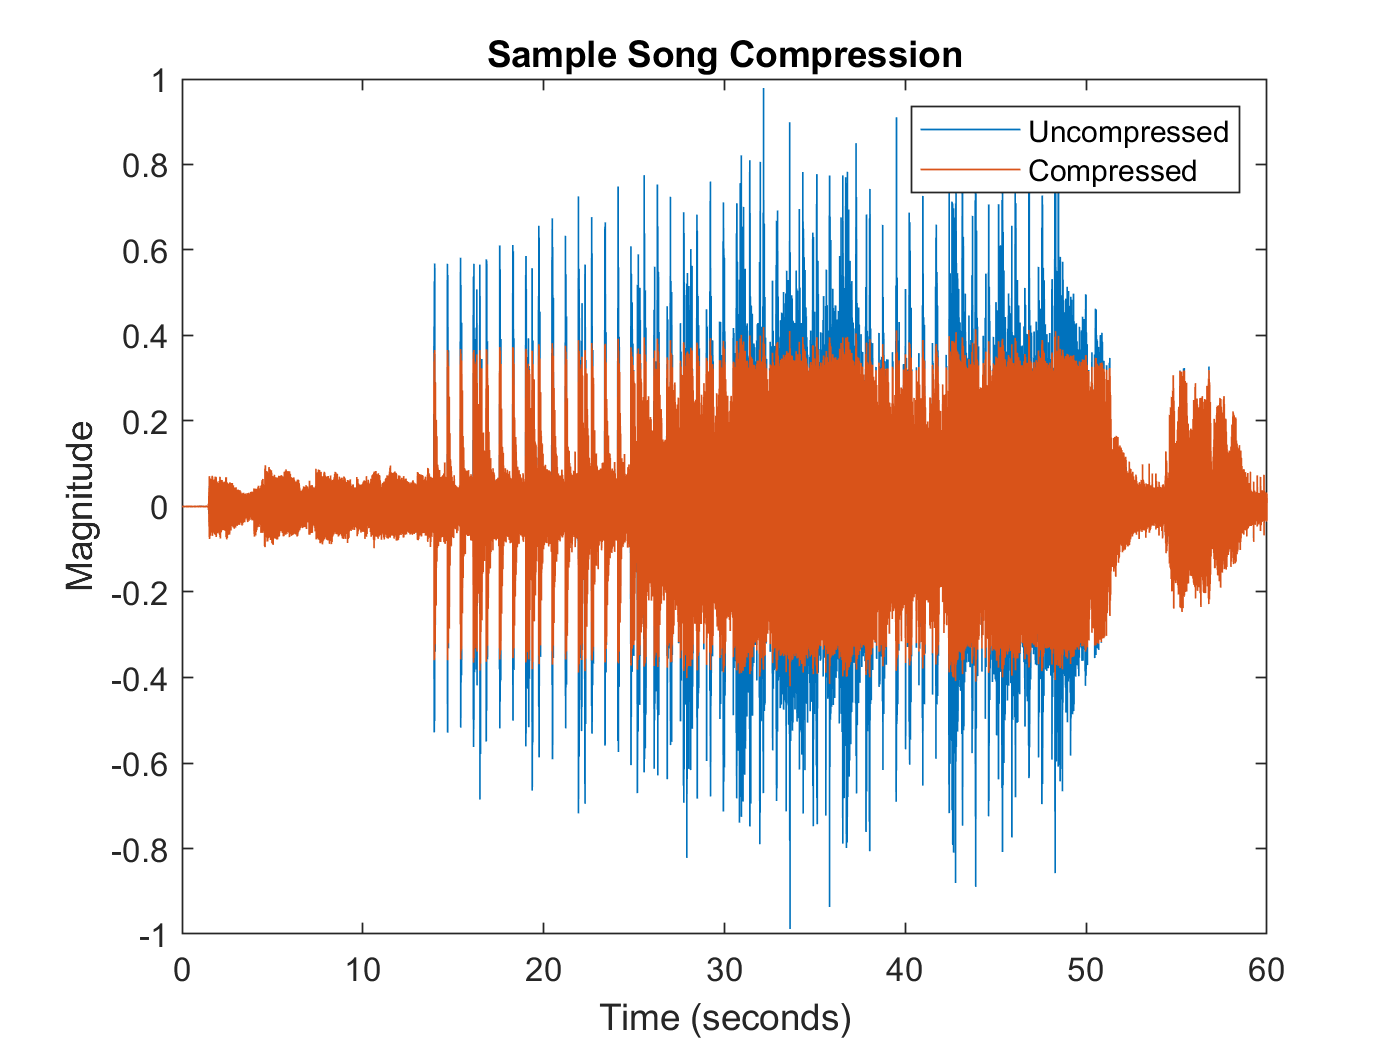

%%Plot the signal
% Time arrays for plots
t_wav = (0:length(wav)-1) / fs;
t_wavComp = (0:length(wavCompressed)-1) / fs;

figure;
plot(t_wav,wav);
hold on;
plot(t_wavComp,wavCompressed);
legend('Uncompressed', 'Compressed');
title("Sample Song Compression");
xlabel("Time (seconds)");
ylabel("Magnitude");